# 6.3 ペアになった分布間の距離指標

### 図 6.3.1 相関として類似度をとらえる

%シード値の設定
rng('default')

% 書籍の数
n_books = 100;

% Aさんのレビュー
a_scores = randn(1, n_books) * 15 + 60;
% a_scores = int32(a_scores);  % データ型をintegerに変換
a_scores = max(min(a_scores,100),0);  % 0から100の範囲にクリップ

% Bさんのレビュー（Aさんと高い相関）
b_scores = a_scores + randn(1, n_books) * 10;
% b_scores = int32(b_scores); % データ型をintegerに変換
b_scores = max(min(b_scores,100),0); % 0から100の範囲にクリップ

% Cさんのレビュー（Aさんと緩い逆相関）
c_scores = 100 - a_scores + randn(1, n_books) * 20;
% c_scores = int32(c_scores); % データ型をintegerに変換
c_scores = max(min(c_scores,100),0); % 0から100の範囲にクリップ

% 結果の表示
disp(['Aさんのレビュー    Bさんのレビュー    Cさんのレビュー'])

Aさんのレビュー    Bさんのレビュー    Cさんのレビュー


disp([num2str(a_scores'), num2str(b_scores'), num2str(c_scores')])

68.0650176.4687635.5995
87.5082878.62795      0
 26.117327.1182392.8671
 72.932667.4873133.2086
64.7814867.81669 37.922
40.3846834.3814169.9203
53.4961258.39577 51.732
65.13937  72.53316.0309
     100     100      0
     10098.05876      0
 39.751718.3681449.6081
     10091.6041133.6421
70.8810684.4270111.6043
59.0541848.3326231.2695
70.7211480.3306815.0388
56.9255158.1660119.5902
58.13783 72.504838.0174
82.3454662.7364612.1731
81.1355279.1585449.4659
81.2578969.1794313.7616
70.0724699.152548.64327
 41.887750.1398990.1814
70.75858 84.5483 53.935
84.4535373.8717310.9539
67.3334162.64725 2.5434
 75.5204 72.7957 15.587
70.9032881.8875225.9779
55.4483952.66967 50.073
64.4080771.4234930.3687
48.1907627.6725960.6777
73.3259369.7874334.5119
42.7939534.5580832.1925
43.9669428.1963737.0738
47.8575252.9372737.3204
15.8357418.6555874.0079
 81.5757 81.910512.0128
64.8778651.5410835.3715
48.67608  59.951      0
80.5544884.0562710.3052
34.3272531.3365990.5217
58.4663658.6952620.1996
56.3782953.75834

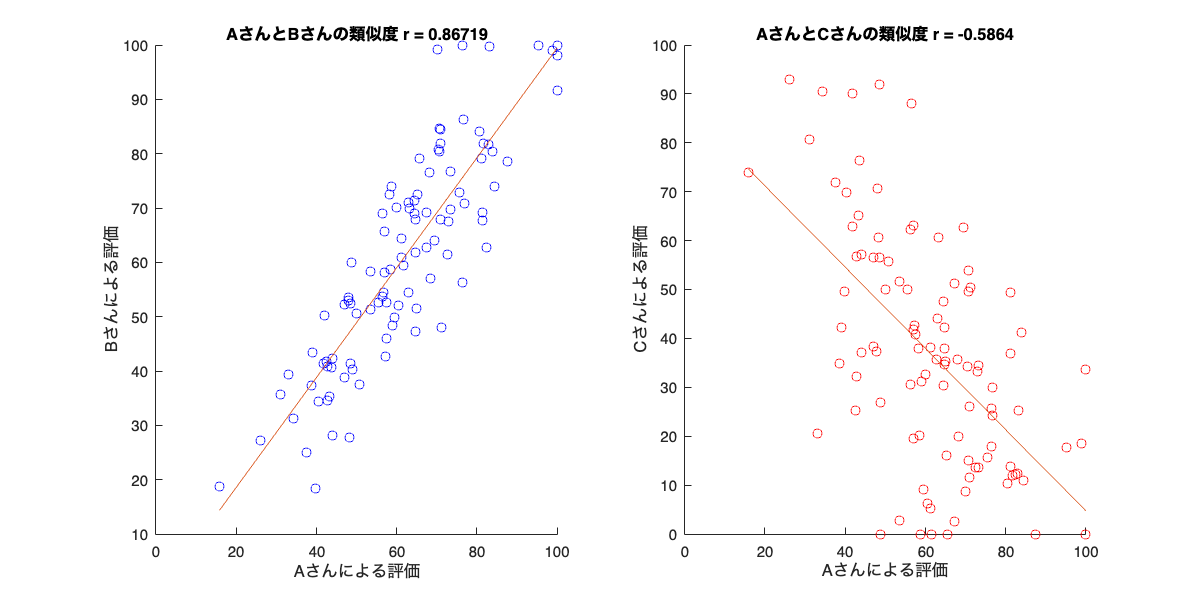


% 相関係数の計算
corr_ab = corrcoef(a_scores, b_scores);
corr_ab = corr_ab(1,2);  % 2次元から1次元へ変換
corr_ac = corrcoef(a_scores, c_scores);
corr_ac = corr_ac(1,2);  % 2次元から1次元へ変換

% 線形回帰の描画
figure('Position',[10 10 800 400])

subplot(1,2,1);  % AさんとBさんのレビューの散布図と線形回帰直線を描画
scatter(a_scores, b_scores, 'blue'); 
hold on;
p = polyfit(a_scores,b_scores,1);
yfit = polyval(p,a_scores);
plot(a_scores,yfit,'-');
hold off;
title(['AさんとBさんの類似度 r = ', num2str(corr_ab)]);  % タイトルを設定
xlabel('Aさんによる評価');  % x軸ラベルを設定
ylabel('Bさんによる評価');  % y軸ラベルを設定

subplot(1,2,2);  % AさんとCさんのレビューの散布図と線形回帰直線を描画
scatter(a_scores, c_scores, 'red'); 
hold on;
p = polyfit(a_scores,c_scores,1);
yfit = polyval(p,a_scores);
plot(a_scores,yfit,'-');
hold off;
title(['AさんとCさんの類似度 r = ', num2str(corr_ac)]);  % タイトルを設定
xlabel('Aさんによる評価');  % x軸ラベルを設定
ylabel('Cさんによる評価');  % y軸ラベルを設定


% 相対スコアを元にコサイン類似度を計算
a_scores_rel = a_scores - mean(a_scores);
b_scores_rel = b_scores - mean(b_scores);
c_scores_rel = c_scores - mean(c_scores);

cos_sim_ab = dot(a_scores_rel, b_scores_rel) / (norm(a_scores_rel) * norm(b_scores_rel));
cos_sim_ac = dot(a_scores_rel, c_scores_rel) / (norm(a_scores_rel) * norm(c_scores_rel));
disp(['コサイン類似度（AさんとBさん）: ', num2str(cos_sim_ab)]);

コサイン類似度（AさんとBさん）: 0.86719


disp(['コサイン類似度（AさんとCさん）: ', num2str(cos_sim_ac)]);

コサイン類似度（AさんとCさん）: -0.5864



% 図の保存
% print('../figures/6_3_1_correlation_similarity','-dpng','-r300'); 

### 図 6.3.2 時系列同士の相関で類似度を測る

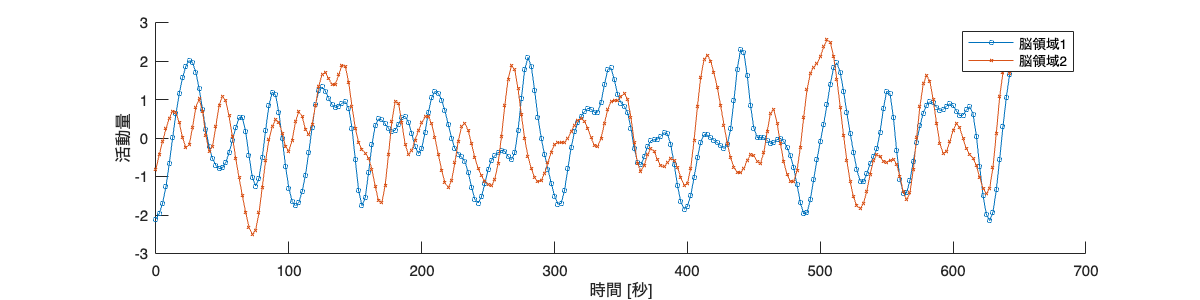

% データを読み込む（著者が準備したサンプルデータ）
path = fullfile("data","brain.txt");
% データをtableに変換
data_df = readtable(path, 'Delimiter', '\t');

% 時刻を1ステップにつき2.5秒に変換（2.5秒に一回のペースで撮像されたデータ）
time_steps = (0:2.5:(height(data_df)-1)*2.5)';

% 時系列の折れ線グラフを描画して保存
fig1 = figure('Position', [10 10 800 200]);
hold on;
plot(time_steps, data_df.ROI1, 'Marker', 'o', 'MarkerSize', 3, 'DisplayName', '脳領域1');
plot(time_steps, data_df.ROI2, 'Marker', 'x', 'MarkerSize', 3, 'DisplayName', '脳領域2');
xlabel('時間 [秒]');  % x軸ラベルを設定
ylabel('活動量');  % y軸ラベルを設定
legend('show');
hold off;

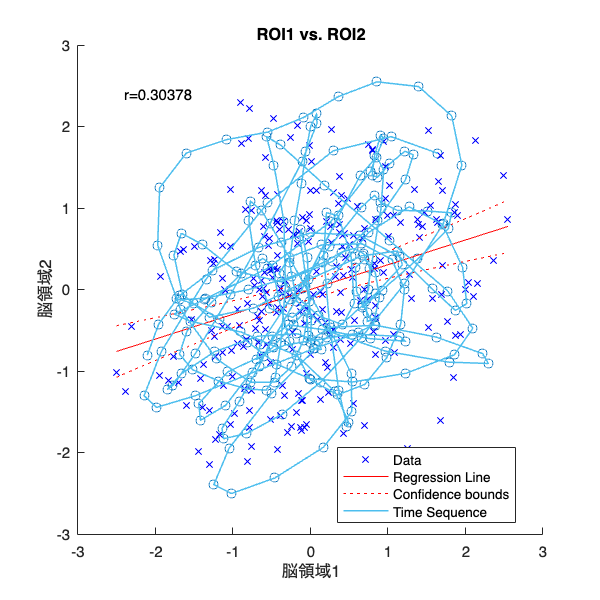


% print('../figures/6_3_2_1_time_series_line_plot', '-dpng', '-r300');  % 図の保存


% r値の計算
[r_value,p_value] = corrcoef(table2array(data_df(:, 'ROI1')), table2array(data_df(:, 'ROI2')));

% 散布図と回帰直線、信頼区間を描画して保存
fig2 = figure('Position', [10 10 400 400]);
hold on;
% 散布図
scatter(data_df.ROI1, data_df.ROI2, 'DisplayName', 'Data Points');
% 回帰直線
mdl = fitlm(data_df, 'ROI1~ROI2');
h = plot(mdl);
set(h(2), 'Color', 'red', 'DisplayName', 'Regression Line');
% set(h(4), 'Color', 'grey', 'DisplayName', '95% Confidence Bounds');
% 時系列を繋ぐ
plot(data_df.ROI1, data_df.ROI2, 'LineStyle', '-', 'LineWidth', 1, 'DisplayName', 'Time Sequence');
xlabel('脳領域1');  % x軸ラベルを設定
ylabel('脳領域2');  % y軸ラベルを設定
% r値をグラフに追加
text(0.1, 0.9, ['r=' num2str(r_value(1,2))], 'Units','Normalized');
legend('show');
hold off;


% print('../figures/6_3_2_2_time_series_scatter_plot', '-dpng', '-r300');  % 図の保存


### 図 6.3.3 サンプリングされた相関係数とフィッシャー変換

### 図 6.3.4 他の変数の影響を考慮して相関をとらえる

### 図 6.3.5 ベクトルのなす角として類似度をとらえる

### 図 6.3.6 予測モデルの誤差